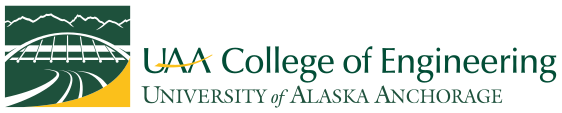

# EE A438 Design of Electrical Engineering Systems

# Electronically Scanned Array Speaker System

## Array Pattern

For the phased array speaker grid, the array pattern that fit best with my project was a simple 5x5 rectangular grid.  Because of some mechanical limitations, a more complex lattice such as a hexagonal or triangular lattice would have been much more difficult to implement.  Using a frequency of 4186Hz (the musical tone C8) the maximum distance between each element before creating grating lobes can easily be calculated.

                                  $\lambda =\frac{c}{f}=\frac{343\frac{m}{s}}{4186\;\textrm{Hz}}=0\ldotp 0819\;m$              $D\;=\frac{\lambda }{2}$ = $0\ldotp 041\;m\;$

As well see later, one half lambda does not entirely eliminate grafting lobes when adding a phase delay to the system.  At around a phase of theta = 55°, large side lobes begin to form.  In order to eliminate these lobes for a wider amount of phase delay, the distance between each element can be decreased to around $\frac{\lambda }{3}=0\ldotp 0273m\ldotp$ For simplicity, the value 0.025m was used.

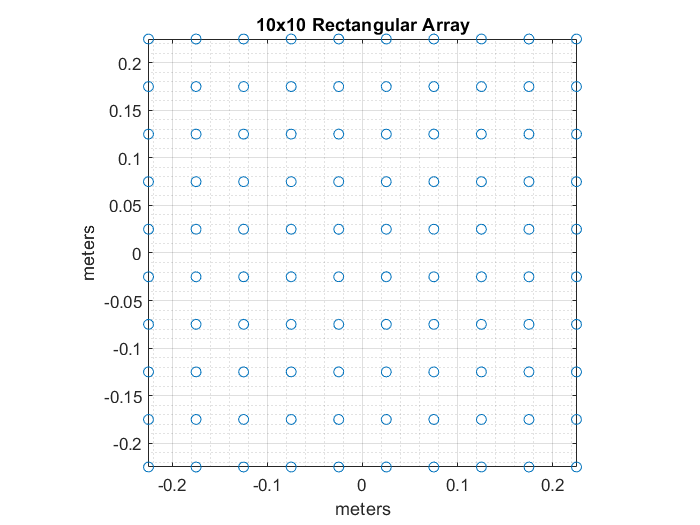

clc
clear all
f1 = 3136;
c = 343;
lambda = c/f1;
n = 10;
n_rect = 1:1:n;
m_rect = 1:1:n;
num = length(n_rect)*length(m_rect);
d_rect = .05;
x_rect1 = (m_rect - 0.5*(length(m_rect) + 1))*d_rect;
y_rect1 = (n_rect - 0.5*(length(n_rect) + 1))*d_rect;
x_rect = repmat(x_rect1, [1,length(m_rect)]);
y_rect = reshape(repmat(y_rect1, [length(n_rect), 1]),1,[]);
x_rect_grid = repmat(x_rect1,[length(n_rect),1]);
y_rect_grid = repmat(y_rect1',[1,length(n_rect)]);
plot(x_rect, y_rect, 'o')
grid on; grid minor; axis('equal'); axis('tight'); xlabel('meters'); ylabel('meters');title(n + "x" + n + " Rectangular Array");

## Array Factor (AF)

The AF or Array factor describes the spatial response of the array elements.  In linear array without a phase delay, the equation of the AF  is fairly easy to analyze only consisting of  the apeture distribution, frequency, element spacing, and angle.  We will desregard the apeture distribution for the time being.

## 
$$\textrm{AF}=\sum_{n=1}^N A_n e^{j\frac{2\pi }{\lambda }x_n \sin \;\theta }$$


The AF has a maximum value of N (the number of array elements) at an angle of $\theta =0$°.  This will act as a good check to ensure there are not any obvious errors.  As well show, the maximum value of the AF will always be the number of elements in the array regardless of dimention.  By adding in the term $\Theta_o =-\frac{2\pi }{\lambda }x_n \sin \left(\theta_o \right)$ the phase delay $\theta_o$ can be introduced into the equation.

## 
$$\textrm{AF}=\sum_{n=1}^N A_n e^{j\left(\frac{2\pi }{\lambda }x_n \;\sin \;\theta -\frac{2\pi }{\lambda }x_n \;\sin \;\theta_o \right)}$$


With a phase delay of $\theta_o =0$°, the equation returns to the previous equation without the phase delay term.  By applying the appropriate phase at each element, the ESA beam can be moved spatially without physically moving the entire array.  In 2 dimentions, the AF becomes a function of both x and y element distances, and angles $\theta$ and $\phi$.

## $\textrm{AF}=\sum_{l=1}^{N*M} C_l e^{j\left(\frac{2\pi }{\lambda }x_{l\;} \sin \;\theta \;\cos \;\phi +\frac{2\pi }{\lambda }y_l \;\sin \;\theta \;\sin \;\phi \right)}$                            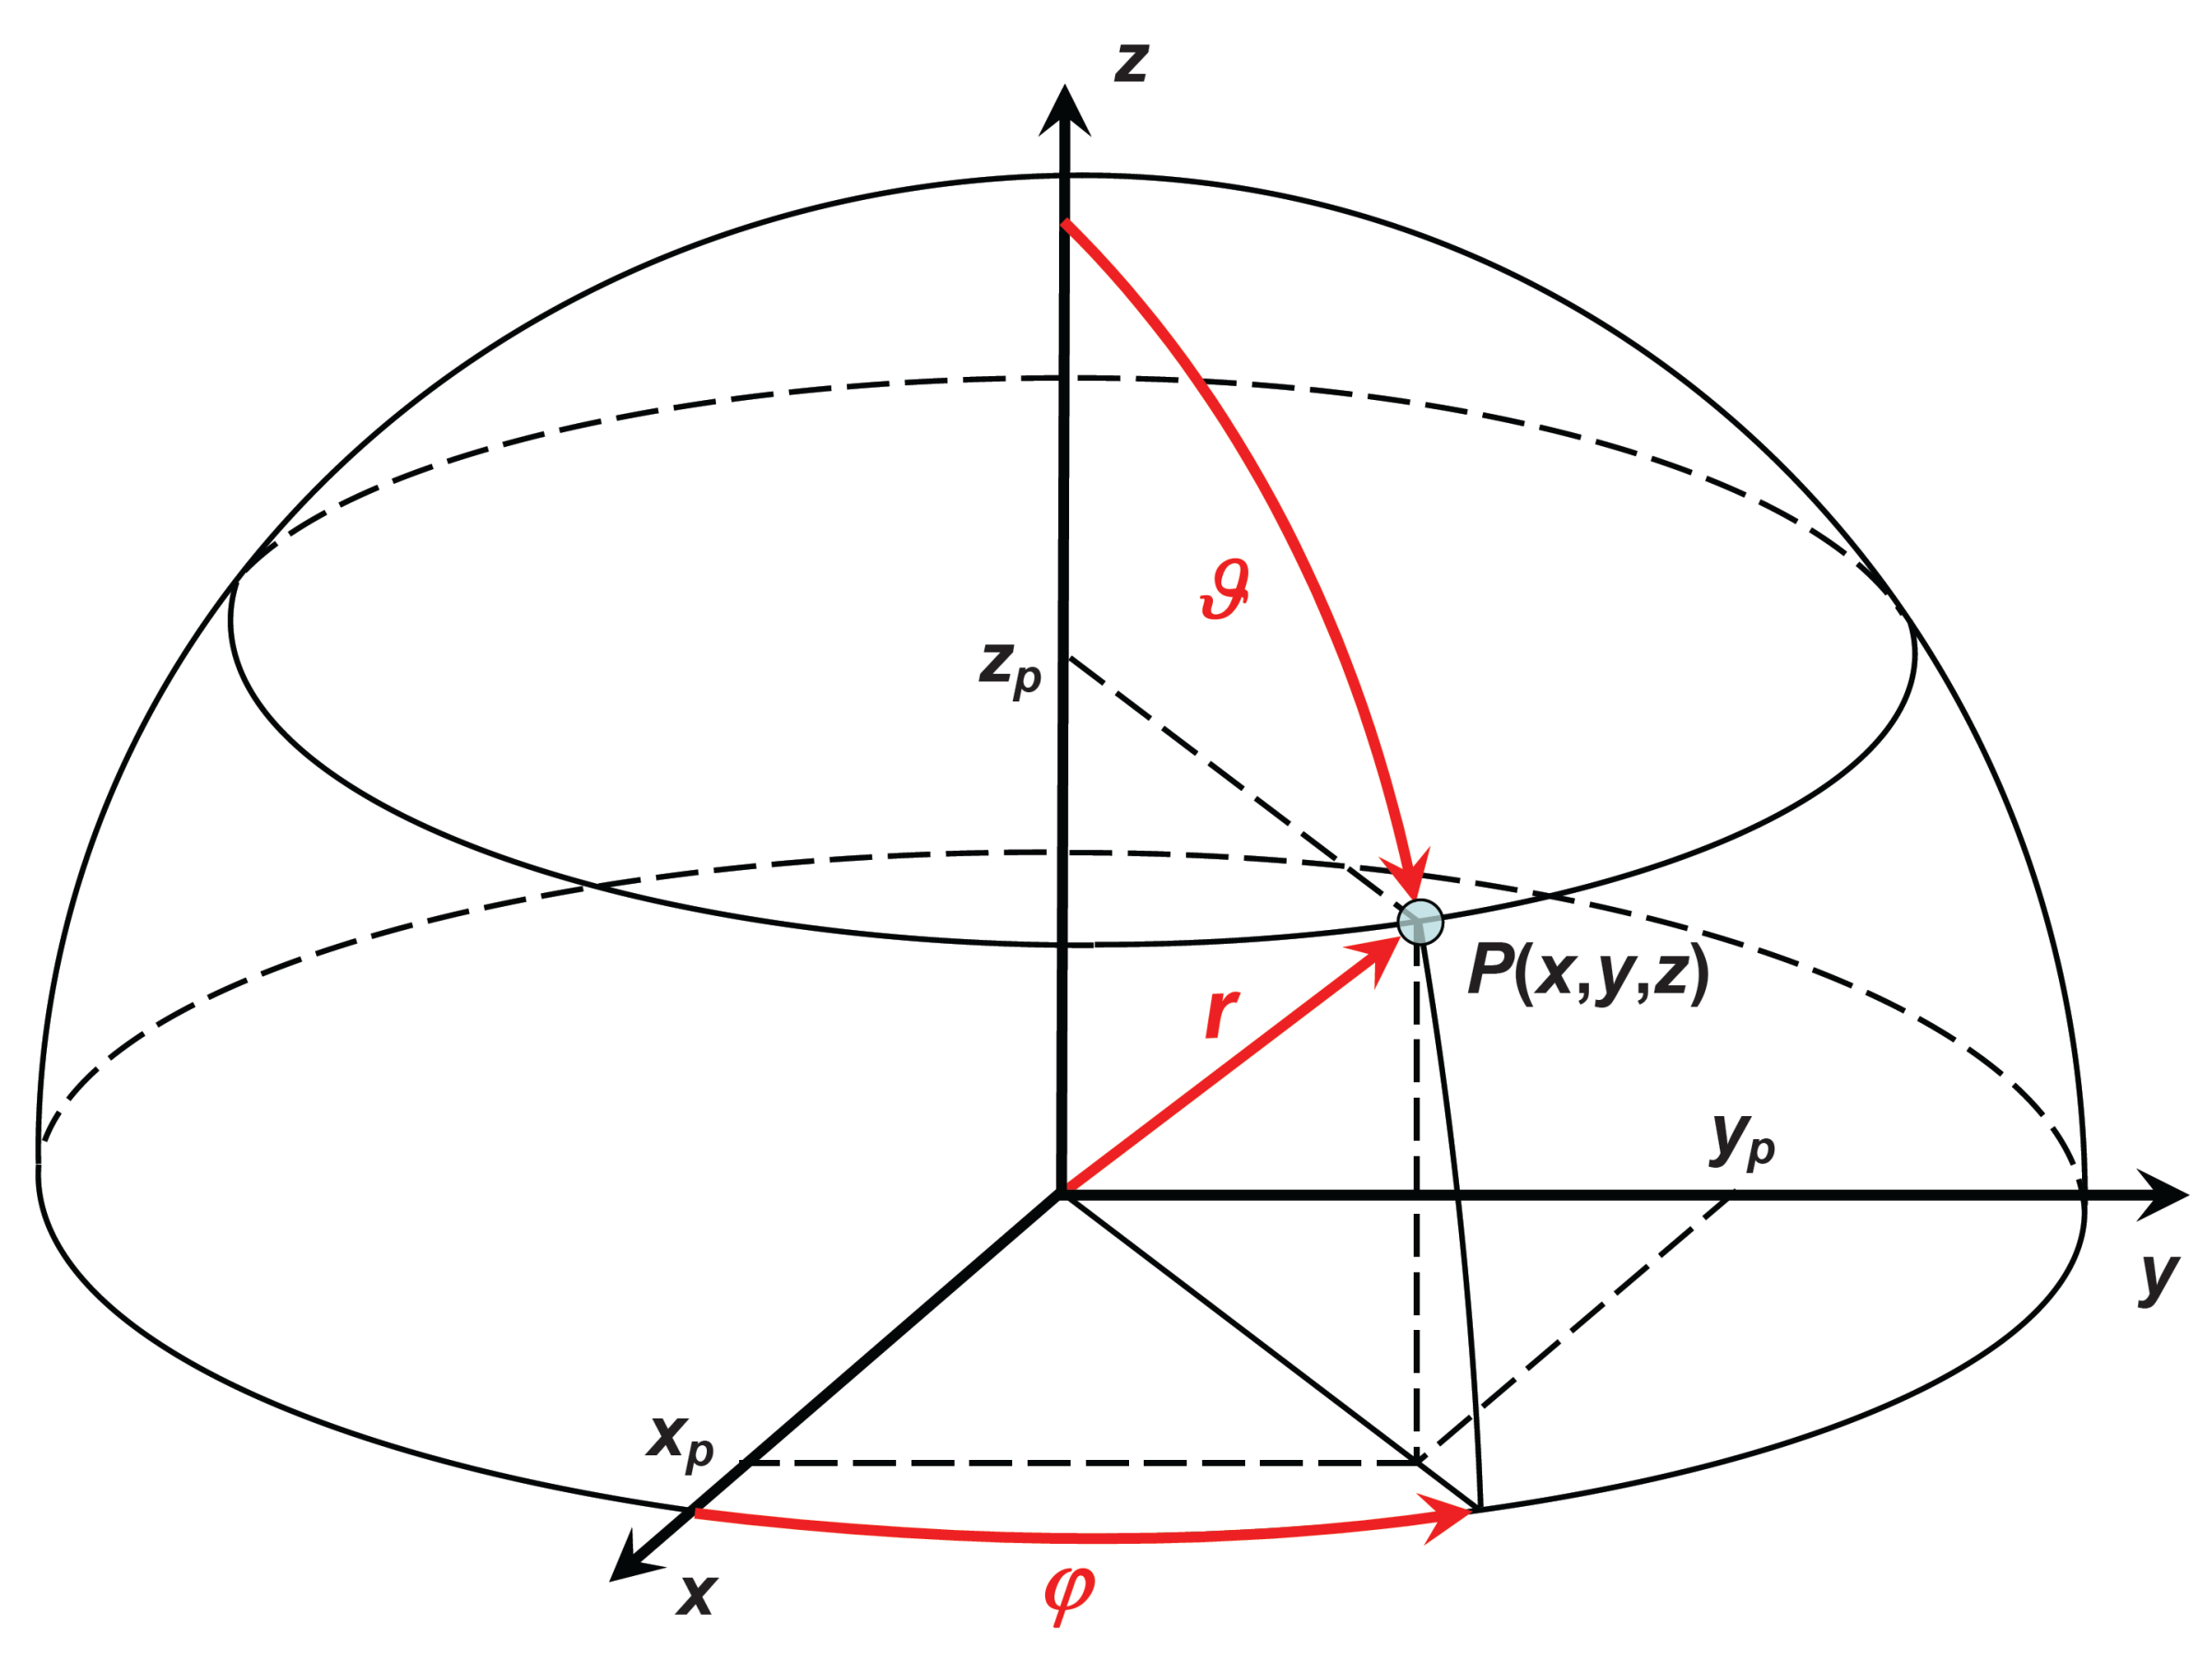

Again, at an angle of $\theta =0$° (the point directly above the array), the AF has a maximum value of the amount of elements in the array.  Now after adding two phase delays, $\theta_o$ and $\phi_o$, the equation of the AF becomes: 

## 
$$\textrm{AF}=\sum_{l=1}^{N*M} C_l \;e^{j\left(\frac{2\pi }{\lambda }x_{l\;} \sin \;\theta \;\cos \;\phi -\frac{2\pi }{\lambda }x_l \;\sin \;\theta_o \;\cos \;\phi_o \right)} e^{j\left(\frac{2\pi }{\lambda }y_{l\;\;} \sin \;\theta \;\sin \;\phi +\frac{2\pi }{\lambda }y_{l\;\;} \sin \;\theta_o \;\sin \;\phi_o \right)}$$


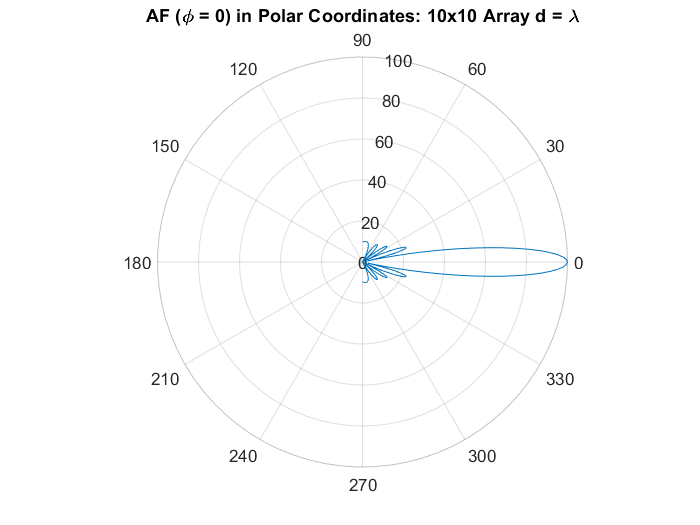

x=x_rect; y=y_rect; weights=1; lambda=c/f1; phi_phase=0; theta_phase=0; EF=1.5;
[AF_nw, EP_nw, phi, theta] = find_array_signal(x, y, weights, lambda, phi_phase, theta_phase, EF);
polarplot(theta, AF_nw(:,1))
title("AF (\phi = 0) in Polar Coordinates: " + n + "x" + n + " Array d = \lambda");

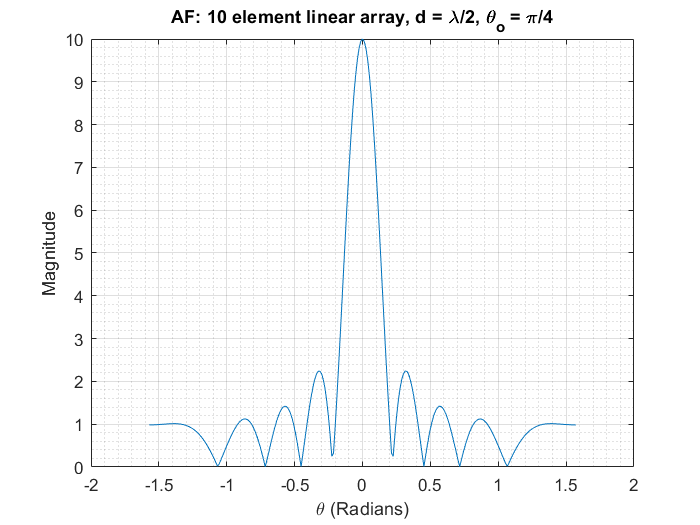

theta_phase = 0;
[AF, EP, theta] = find_array_signal_linear(x_rect1, weights, lambda, theta_phase, EF);
plot(theta, AF)
grid on; grid minor; title("AF: 10 element linear array, d = \lambda/2, \theta_{o} = \pi/4"); ylabel('Magnitude'); xlabel('\theta (Radians)')

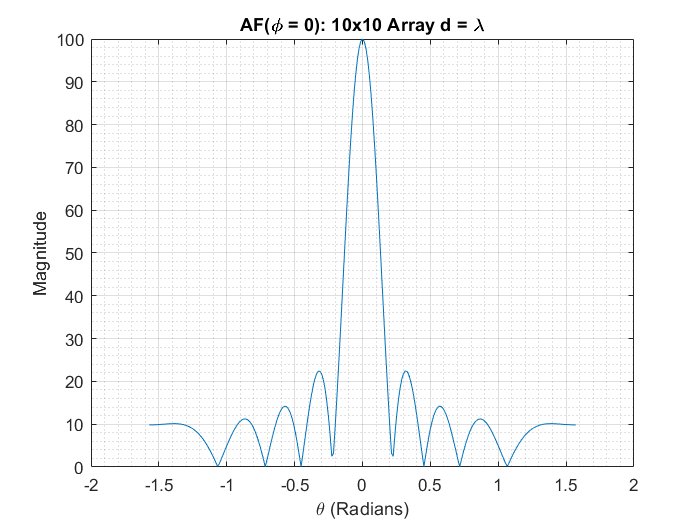

plot(theta, AF_nw(:,1))
grid on; grid minor; title("AF(\phi = 0): " + n + "x" + n + " Array d = \lambda"); ylabel('Magnitude'); xlabel('\theta (Radians)')

## Element Pattern (EP) and Complete Pattern Representation (F)

## 
$$F_{\textrm{dB}} =10\textrm{lo}g_{10} {\left(\textrm{EP}*\textrm{AF}\right)}^2$$


The AF does not completely describe the spatial response of the array.  Each of the element in the array has an element patten that is the elements spatial response.  A good expression for mobeling the element patern is a cosine function raised to a power that is called the element factor (EF). The expression for the element pattern (EP) is:

##                    
$$\textrm{EP}=\cos^{\frac{\textrm{EF}}{2}} \theta$$


The complete pattern representation for the array can be found by multiplying the AF and EF together:

## 
$${F\left(\theta \right)\;=\;\textrm{EP}*\textrm{AF}\;=\;\cos }^{\frac{\textrm{EF}}{2}} \theta *\sum_{l=1}^{N*M} C_l \;e^{j\left(\frac{2\pi }{\lambda }x_{l\;} \sin \;\theta \;\cos \;\phi -\frac{2\pi }{\lambda }x_l \;\sin \;\theta_o \;\cos \;\phi_o \right)} e^{j\left(\frac{2\pi }{\lambda }y_{l\;\;} \sin \;\theta \;\sin \;\phi +\frac{2\pi }{\lambda }y_{l\;\;} \sin \;\theta_o \;\sin \;\phi_o \right)}$$



$$F_{\textrm{dB}} =10\textrm{lo}g_{10} {\left(\textrm{EP}*\textrm{AF}\right)}^2$$


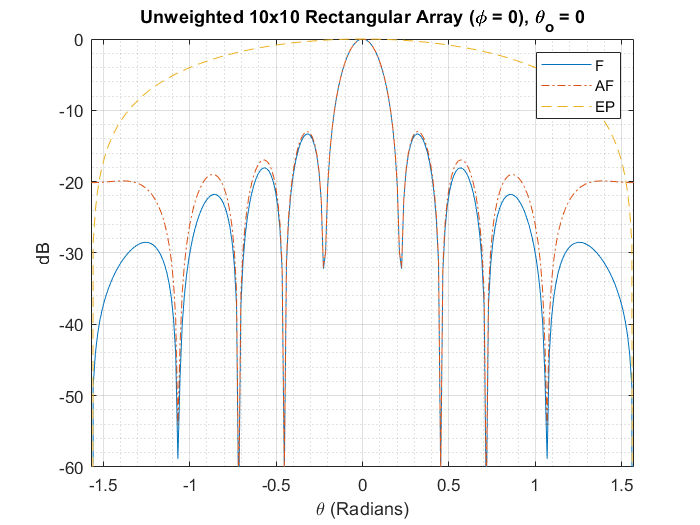

AF_nw_norm = AF_nw./max(AF_nw);
EP_nw_norm = EP_nw./max(EP_nw);
AF_nw_db = 20*log10(AF_nw_norm);
EP_nw_db = 20*log10(EP_nw_norm);
F_nw = AF_nw.*EP_nw;
F_nw_norm = AF_nw_norm.*EP_nw_norm;
F_nw_db = AF_nw_db+EP_nw_db;
plot(theta, F_nw_db(:,1));
grid on; grid minor; hold on;
plot(theta, AF_nw_db(:,1), '-.');
plot(theta, EP_nw_db(:,1), '--');
hold off; legend('F','AF','EP'); axis('tight'); ylim([-60,0]); xlabel('\theta (Radians)'); ylabel('dB'); title("Unweighted " + n + "x" + n + " Rectangular Array (\phi = 0), \theta_{o} = 0");

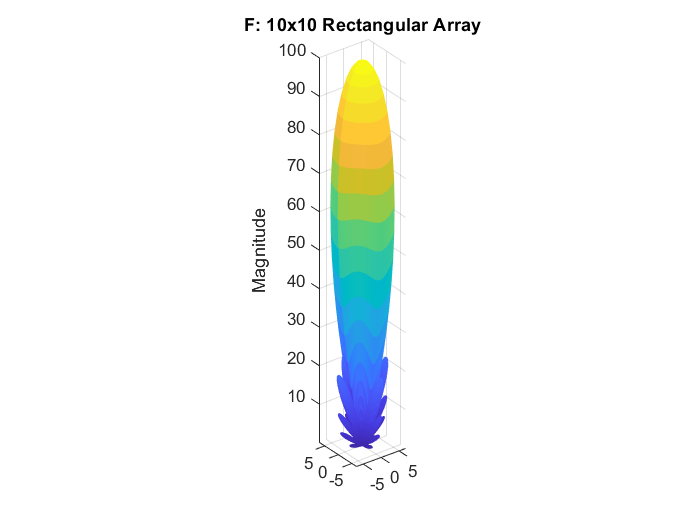

[Phi, Theta]=meshgrid(phi,theta);
Z = F_nw.*cos(Theta);
X = F_nw.*cos(Phi).*sin(Theta);
Y = F_nw.*sin(Phi).*sin(Theta);
mesh(X,Y,Z)
axis(['tight']);axis('equal'); 
title("F: " + n + "x" + n + " Rectangular Array")
zlabel('Magnitude')

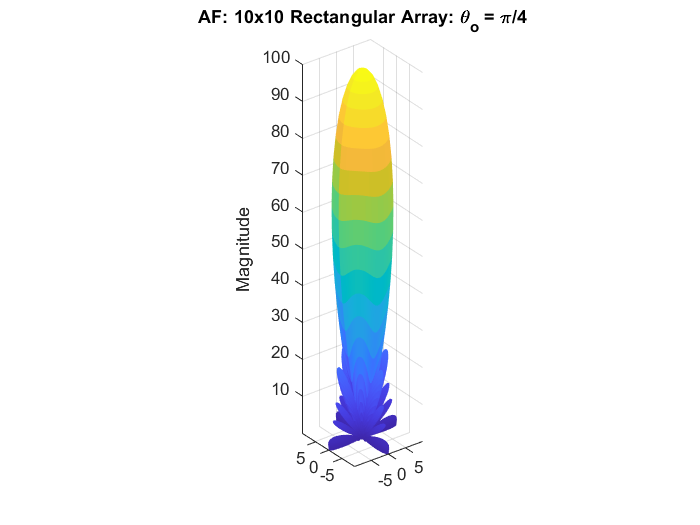

Z = AF_nw.*cos(Theta);
X = AF_nw.*cos(Phi).*sin(Theta);
Y = AF_nw.*sin(Phi).*sin(Theta);
mesh(X,Y,Z)
axis(['square']);axis('equal'); 
title("AF: " + n + "x" + n + " Rectangular Array: \theta_{o} = \pi/4")
zlabel('Magnitude')

Adding a phase angle:

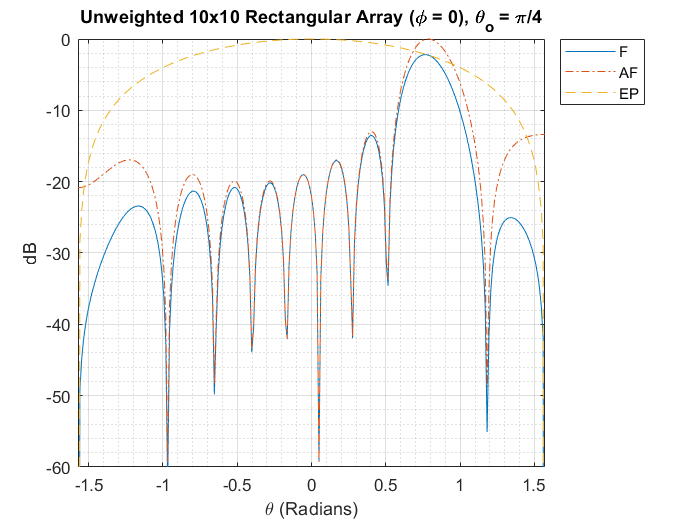

x=x_rect; y=y_rect; weights=1; lambda=c/f1; phi_phase=0; theta_phase=pi/4; EF=1.5;
[AF_nw_phase, EP_nw_phase, phi, theta] = find_array_signal(x, y, weights, lambda, phi_phase, theta_phase, EF);
AF_nw_norm_phase = AF_nw_phase./max(AF_nw_phase);
EP_nw_norm_phase = EP_nw_phase./max(EP_nw_phase);
AF_nw_db_phase = 20*log10(AF_nw_norm_phase);
EP_nw_db_phase = 20*log10(EP_nw_norm_phase);
F_nw_phase = AF_nw_phase.*EP_nw_phase;
F_nw_norm_phase = AF_nw_norm_phase.*EP_nw_norm_phase;
F_nw_db_phase = AF_nw_db_phase+EP_nw_db_phase;
plot(theta, F_nw_db_phase(:,1));
grid on; grid minor; hold on;
plot(theta, AF_nw_db_phase(:,1), '-.');
plot(theta, EP_nw_db_phase(:,1), '--');
hold off; legend('F','AF','EP'); axis('tight'); ylim([-60,0]); xlabel('\theta (Radians)'); ylabel('dB'); title("Unweighted " + n + "x" + n + " Rectangular Array (\phi = 0), \theta_{o} = \pi/4");

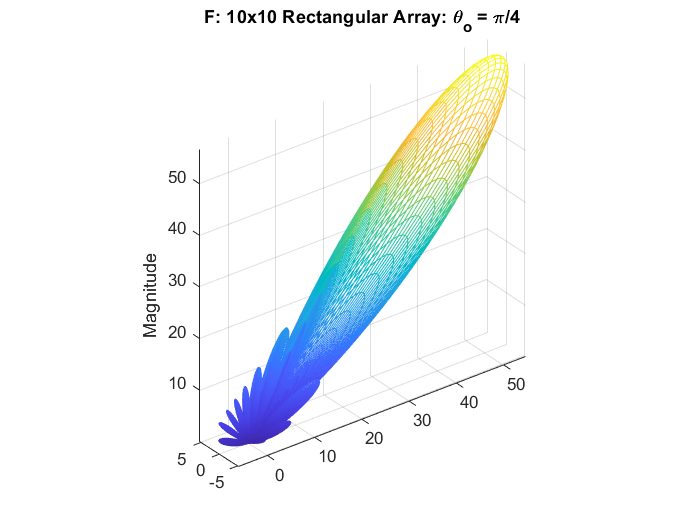

[Phi, Theta]=meshgrid(phi,theta);
Z = F_nw_phase.*cos(Theta);
X = F_nw_phase.*cos(Phi).*sin(Theta);
Y = F_nw_phase.*sin(Phi).*sin(Theta);
mesh(X,Y,Z)
axis(['tight']);axis('equal'); 
title("F: " + n + "x" + n + " Rectangular Array: \theta_{o} = \pi/4")
zlabel('Magnitude')

## Element Weighting

In order to lower sidelobes, the element amplitudes or the apature distribution can be modified.  There are various types of amplitude weightings, however, taylor weighting is the most efficient aperture distribution.

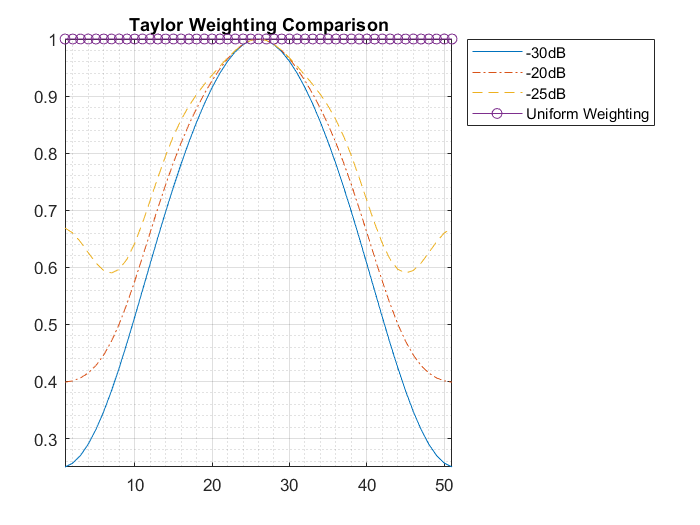

sll = 30;
nbar = 3;
x_axis = [1:1:51];
weights_flat = ones([1,51]);
weights_taylor_30 = find_taylor_weights([1:51], 30, 5);
weights_taylor_25 = find_taylor_weights([1:51], 25, 5);
weights_taylor_20 = find_taylor_weights([1:51], 20, 5);
plot(x_axis, weights_taylor_30, '-', x_axis, weights_taylor_25, '-.', x_axis, weights_taylor_20, '--', x_axis, weights_flat, 'o-')
grid on;grid minor;axis('tight');legend('-30dB','-20dB','-25dB','Uniform Weighting');title('Taylor Weighting Comparison')

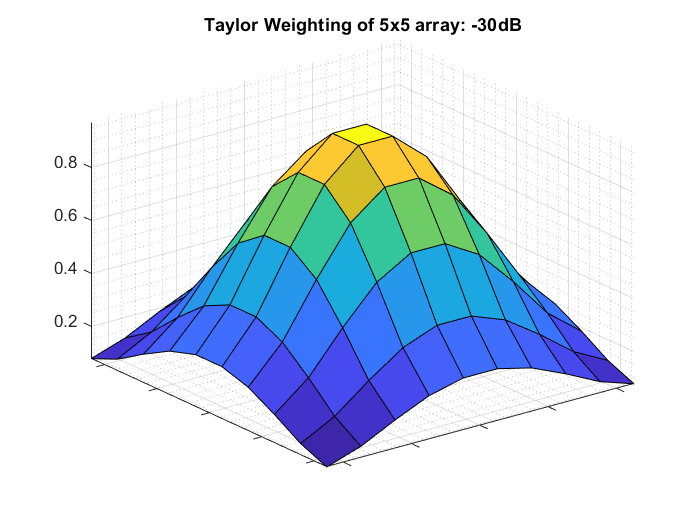

% weights = reshape(weights.*weights',1,[]);
% plot3(x_rect,y_rect,weights, 'o')
% title('Taylor Weighting for a Rectangular Array')
% zlabel('Weight')
% xlabel('X-axis')
% ylabel('Y-axis')

weights_taylor_30 = find_taylor_weights(n_rect, 30, nbar);
weights_taylor_25 = find_taylor_weights(n_rect, 25, nbar);
weights_taylor_20 = find_taylor_weights(n_rect, 20, nbar);

surf(x_rect_grid, y_rect_grid, weights_taylor_30.*weights_taylor_30')
grid on;grid minor;axis('tight');set(gca,'YTickLabel',[]);set(gca,'XTickLabel',[]);title('Taylor Weighting of 5x5 array: -30dB')

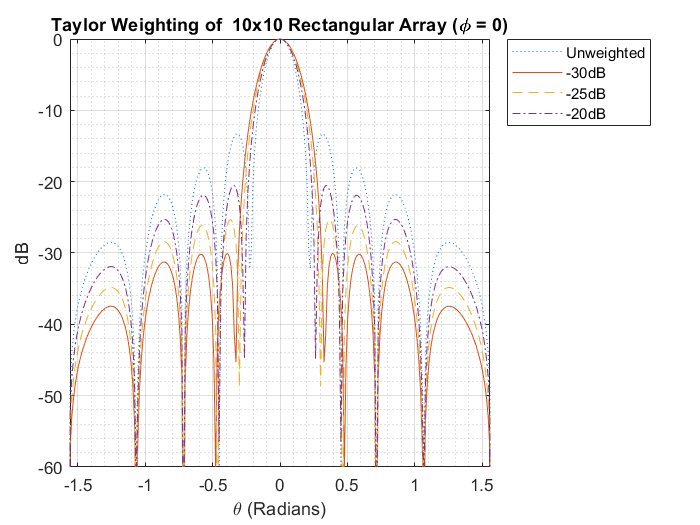


weights_taylor_30 = reshape(weights_taylor_30.*weights_taylor_30',1,[]);
weights_taylor_25 = reshape(weights_taylor_25.*weights_taylor_25',1,[]);
weights_taylor_20 = reshape(weights_taylor_20.*weights_taylor_20',1,[]);

x=x_rect; y=y_rect; weights=weights_taylor_30; lambda=c/f1; phi_phase=0; theta_phase=0; EF=1.5;
[AF_30, EP_30, phi, theta] = find_array_signal(x, y, weights, lambda, phi_phase, theta_phase, EF);
AF_30_norm = AF_30./max(AF_30);
EP_30_norm = EP_30./max(EP_30);
AF_30_db = 20*log10(AF_30_norm);
EP_30_db = 20*log10(EP_30_norm);
F_30 = AF_30.*EP_30;
F_30_norm = AF_30_norm.*EP_30_norm;
F_30_db = AF_30_db+EP_30_db;

x=x_rect; y=y_rect; weights=weights_taylor_25; lambda=c/f1; phi_phase=0; theta_phase=0; EF=1.5;
[AF_25, EP_25, phi, theta] = find_array_signal(x, y, weights, lambda, phi_phase, theta_phase, EF);
AF_25_norm = AF_25./max(AF_25);
EP_25_norm = EP_25./max(EP_25);
AF_25_db = 20*log10(AF_25_norm);
EP_25_db = 20*log10(EP_25_norm);
F_25 = AF_25.*EP_25;
F_25_norm = AF_25_norm.*EP_25_norm;
F_25_db = AF_25_db+EP_25_db;

x=x_rect; y=y_rect; weights=weights_taylor_20; lambda=c/f1; phi_phase=0; theta_phase=0; EF=1.5;
[AF_20, EP_20, phi, theta] = find_array_signal(x, y, weights, lambda, phi_phase, theta_phase, EF);
AF_20_norm = AF_20./max(AF_20);
EP_20_norm = EP_20./max(EP_20);
AF_20_db = 20*log10(AF_20_norm);
EP_20_db = 20*log10(EP_20_norm);
F_20 = AF_20.*EP_20;
F_20_norm = AF_20_norm.*EP_20_norm;
F_20_db = AF_20_db+EP_20_db;

plot(theta, F_nw_db(:,1), ':', theta, F_30_db(:,1), '-', theta, F_25_db(:,1),'--', theta, F_20_db(:,1), '-.');
grid on; grid minor; legend('Unweighted','-30dB','-25dB','-20dB'); axis('tight'); ylim([-60,0]); xlabel('\theta (Radians)'); ylabel('dB'); title("Taylor Weighting of  " + n + "x" + n + " Rectangular Array (\phi = 0)");

## Using an Arduino to add time delays

format shortE
theta_phase_original = pi/4;
time = repmat(sin(theta_phase_original)*2*pi*d_rect/c*(n_rect-1), [n,1]);
toneTime = 11.7E-6*(n_rect-1);
microsTime = 8E-6;
slack = time-toneTime;
timeDelay1 = round(slack/microsTime)*microsTime;
timeDelay = timeDelay1+toneTime;
theta_phase_error = repmat(asin(c./(2*pi*d_rect*(n_rect-1)).*timeDelay(1,:)), [1,n]);


$$\theta_o =\sin^{-1} \left(\frac{c}{2\pi d}\delta t\right)$$


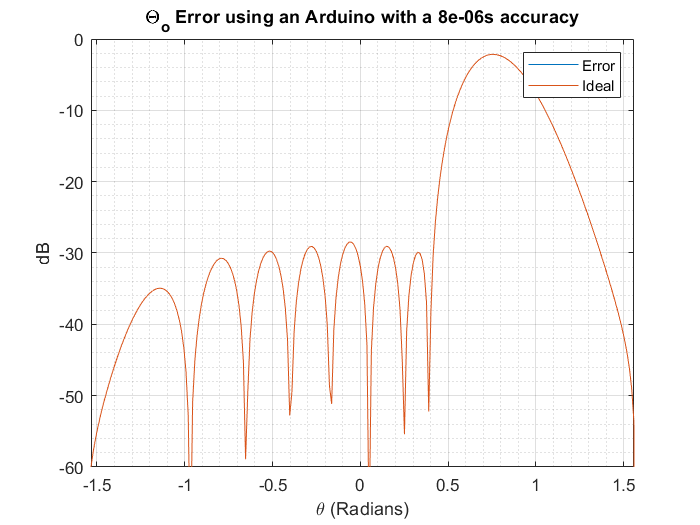

x=x_rect; y=y_rect; weights=weights_taylor_30; lambda=c/f1; phi_phase=0; theta_phase=theta_phase_error; EF=1.5;
[AF_error, EP_error, phi, theta] = find_array_signal(x, y, weights, lambda, phi_phase, theta_phase, EF);
AF_norm_error = AF_error./max(AF_error);
EP_norm_error = EP_error./max(EP_error);
AF_db_error = 20*log10(AF_norm_error);
EP_db_error = 20*log10(EP_norm_error);

F_error = AF_error.*EP_error;
F_norm_error = AF_norm_error.*EP_norm_error;
F_db_error = AF_db_error+EP_db_error;

x=x_rect; y=y_rect; weights=weights_taylor_30; lambda=c/f1; phi_phase=0; theta_phase=theta_phase_original; EF=1.5;
[AF, EP, phi, theta] = find_array_signal(x, y, weights, lambda, phi_phase, theta_phase, EF);
AF_norm = AF./max(AF);
EP_norm = EP./max(EP);
AF_db = 20*log10(AF_norm);
EP_db = 20*log10(EP_norm);
F = AF.*EP;
F_norm = AF_norm.*EP_norm;
F_db = AF_db+EP_db;

plot(theta, F_db_error(:,1), theta, F_db(:,1))
grid on; grid minor; legend('Error', 'Ideal'); axis('tight'); ylim([-60,0]); xlabel('\theta (Radians)'); ylabel('dB'); title("\Theta_o Error using an Arduino with a " + microsTime + "s accuracy");

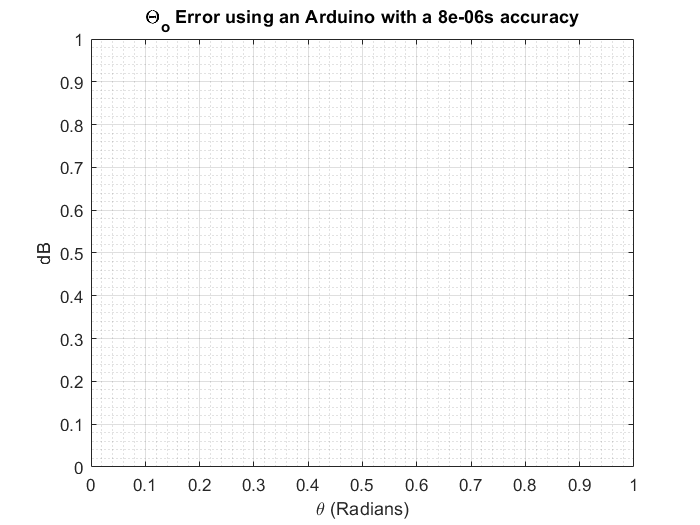

Error_Dif = F - F_error;
plot(theta, Error_Dif(:,1))
grid on; grid minor; axis('tight'); xlabel('\theta (Radians)'); ylabel('dB'); title("\Theta_o Error using an Arduino with a " + microsTime + "s accuracy");

## **Voltage Dividers to Apply Aperture Distribution**

format short
ideal_weights = weights_taylor_30;
V1 = 3.71;
Vout = V1*ideal_weights;
Rb = 15.2;
R = Rb*(V1./Vout)-Rb;
R = [115, 42, 29.5, 42, 115, 42, 10, 4.07, 10, 42, 29.5, 4.07, 0, 4.07,29.5, 42, 10, 4.07, 10, 42, 115, 42, 29.5, 42, 115];
p = 1;
Vout_error = V1*Rb./(R+Rb);
Weights_error = Vout_error/V1;
x=x_rect; y=y_rect; weights=Weights_error; lambda=c/f1; phi_phase=0; theta_phase=0; EF=1.5;
[AF_R, EP_R, phi, theta] = find_array_signal(x, y, weights, lambda, phi_phase, theta_phase, EF);

Matrix dimensions must agree.

Error in find_array_signal (line 15)
        AF(i,j) = abs((sum(weights.*exp(1j*((Tx-Tx_phase))).*exp(1j*(Ty-Ty_phase)))));

AF_R_norm= AF_R./max(AF_R);
EP_R_norm = EP_R./max(EP_R);
AF_R_db = 20*log10(AF_R_norm);
EP_R_db = 20*log10(EP_R_norm);
F_R = AF_R.*EP_R;
F_R_norm = AF_R_norm.*EP_R_norm;
F_R_db = AF_R_db+EP_R_db;
plot(theta, F_R_db(:,1), theta, F_30_db(:,1))
grid on; grid minor; legend('Error', 'Ideal'); axis('tight'); xlabel('\theta (Radians)'); ylim([-60,0]); ylabel('dB'); title("Error using an Non-Ideal Resistor Values");
Rdiff = F_R_db -F_30_db;
plot(theta, Rdiff(:,1))
grid on; grid minor; axis('tight'); xlabel('\theta (Radians)'); ylim([-5,5]); ylabel('dB'); title("Error using an Non-Ideal Resistor Values");

## Phased Speaker Array Results

plot(theta*180/pi, F_norm(:,1)*14 + 45)
grid on; grid minor;

Data_nophase = xlsread('PhasedSpeakerArrayData.xlsx', 'B3:B39');
Data_phasepos = xlsread('PhasedSpeakerArrayData.xlsx', 'e3:e39');
Data_phaseneg = xlsread('PhasedSpeakerArrayData.xlsx', 'h3:h39');
thetad = [-90:5:90];
plot(thetad, Data_phasepos, 'b:o', theta*180/pi, 10*log10(F(:,1))+42)
grid on; grid minor; xlabel('\theta (Degrees)'); axis('tight'); ylabel('dB'); ylim([30,60]); title("Results: Data with \theta_{o} = \pi/4");

